  

**Attention:  **

- this script takes **5 minutes** on Brad's P50 laptop using the Parallel Computing Toolbox(PCT)

- this script takes **10 minutes to run** without the PCT

- The evaluation of the Lagrangian equation is VERY fast ... the time consuming part is binning the derived terms into an M,C,K, ie:  $M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$

- If you are simply interested in the "result", then open the Simulink model called <**COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors.slx**>.  The little YELLOW block inside the masked subsystem is the automatically created MATLAB Function block produced by the Symbolic toolbox

`Bradley Horton : 25-Oct-2017, bradley.horton@mathworks.com.au`

# Task:  Lagrangian approach for deriving Eoms for a **Quadcopter** balancing a **pendulum**

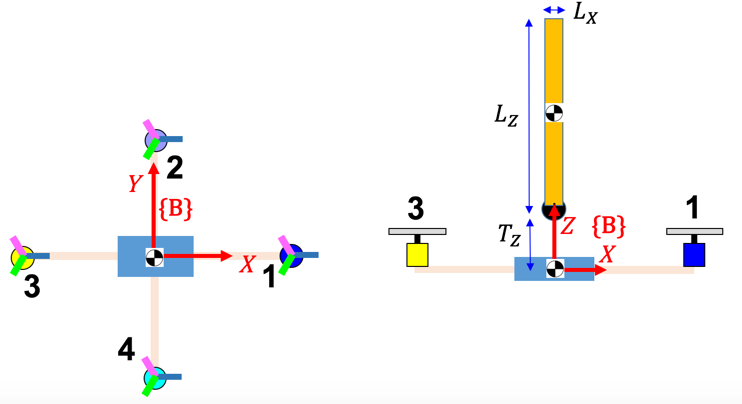  

In this task we're going to look at how the Lagrangian Dynamics approach can be used to derive the equations of motion of a quadcopter balancing an inverted pendulum.  Steps that we'll take will include:

- What is a PASSIVE rotation matrix ?

- How do i construct a Direction Cosine Matrix (DCM) from a given rotation sequence ?

- What is the relationship between BODy rates and EULER rates ?

- What is the KE and PE of just the airframe ?

- What is the KE and PE of each rotor+Propeller assembly ?

- Apply Lagrange's equation to derive the system EoMs

**Euler-Lagrange equations:**

The Euler-Lagrange formula will be used to derive the equations of motion for a Rigid Body, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 25-Oct-2017, bradley.horton@mathworks.com.au`

  Change History:

- `20-Sep-2019 - `a local `cross()` function is defined as a SUBFUNCTION in this script.  This ensures consistent behavior with R2019b

# **Airframe Euler angles and Euler rates**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

Assume that we orientate a body in space via 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

Two key concepts described in the above script are:

- 
$$A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{\omega_x \cr \omega_y \cr \omega_z}  $$


- $\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$      where     $\bf ^BR_G = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z)$

We have implemented the calculations for $\bf ^BR_G$ and  **A **into the Live Function `bh_func_calc_euler_bRg_ZYX`

syms phi theta psi
 
if( string( version('-release'))   >= "2018a" )  % relational comparison with strings is done lexicographically (ie alphabetical)
    [bRg, A] = bh_func_calc_euler_bRg_ZYX()    
else
    [bRg, A] = LOC_collect_euler_concepts()
end                         

$$bRg = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

$$A = \left(\begin{array}{ccc} -\sin\left(\theta \right) & 0 & 1\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 \end{array}\right)$$

# **Airframe generalised co-ordinates:**

**ATTENTION:**

In our Lagrangian derivation we'll make the following assumptions:

- The electric motors are in semi steady state, ie: we'll assume that $K_a \ldotp i\;-\;b\ldotp \omega -\tau_{\textrm{DRAG}} =0$

- This means that the motor reaction torque applied to the quadcopter AIRFRAME is equivalent to $\tau_{\textrm{DRAG}}$

## Euler angles for vehicle:

syms        Phi(t)      Theta(t)       Psi(t)    
syms    THE_Phi     THE_Theta      THE_Psi

## BODY {B}-frame Thrusts and yaw torques

syms Tbz_1  Tbz_2  Tbz_3  Tbz_4
syms Mbz_1  Mbz_2  Mbz_3  Mbz_4

## INERTIAL {G}-frame co-ordinates:

syms         X(t)      Y(t)      Z(t)
syms     THE_X     THE_Y     THE_Z

Inertias, mass and gravity of the Airframe body (this excludes the spinning rotor and propeller assemblies):

syms I_xx I_xy I_xz I_yy I_yz I_zz
syms m
syms g

I = [  I_xx,  I_xy,  I_xz;
       I_xy,  I_yy,  I_yz;
       I_xz,  I_yz,  I_zz   ];

Inertia and mass of ***a single*** spinning propeller assembly:

syms Iprop_xx Iprop_xy Iprop_xz Iprop_yy Iprop_yz Iprop_zz
syms mprop

Iprop = [  Iprop_xx,  Iprop_xy,  Iprop_xz;
           Iprop_xy,  Iprop_yy,  Iprop_yz;
           Iprop_xz,  Iprop_yz,  Iprop_zz   ];

The spin velocities of the propeller assembly relative to the BODY fixed airframe {B}-FRAME:

syms wMOT_1  wMOT_2  wMOT_3  wMOT_4

wMOT_list = [wMOT_1;  wMOT_2;  wMOT_3;  wMOT_4];

For the next 2 lists, it's important that we use the same ordering for our symbols:

actual_list_SYM_pos = [    Phi(t),      Theta(t),      Psi(t),      X(t),      Y(t),      Z(t)];
holder_list_SYM_pos = [THE_Phi,     THE_Theta,     THE_Psi,     THE_X,     THE_Y,     THE_Z   ];                             

In the previous section we derived the relationship between body rates and Euler rates.  So let's just insert our NEW symbols.  Recall that:         $\matrix{
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$  

                % OLD_list          NEW_list
A     = subs(A, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)])

$$A = \left(\begin{array}{ccc} -\sin\left(\Theta \left(t\right)\right) & 0 & 1\\ \cos\left(\Theta \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right) & \cos\left(\Psi \left(t\right)\right) & 0\\ \cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right) & -\sin\left(\Psi \left(t\right)\right) & 0 \end{array}\right)$$


e_dot = [ diff(Phi(t),   t);
          diff(Theta(t), t); 
          diff(Psi(t),   t) ]

$$e\_dot = \left(\begin{array}{c} \frac{\partial }{\partial t}\Phi \left(t\right)\\ \frac{\partial }{\partial t}\Theta \left(t\right)\\ \frac{\partial }{\partial t}\Psi \left(t\right) \end{array}\right)$$


w     = A * e_dot;      

Define the Direction Cosine Matrix using our new symbols:

                          % OLD_list          NEW_list
bRg_again = subs(bRg, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)]);
gRb_again = (bRg_again).';

# Airframe Translational and Angular velocities and Altitude:

Say our Quadcopter looks like this:

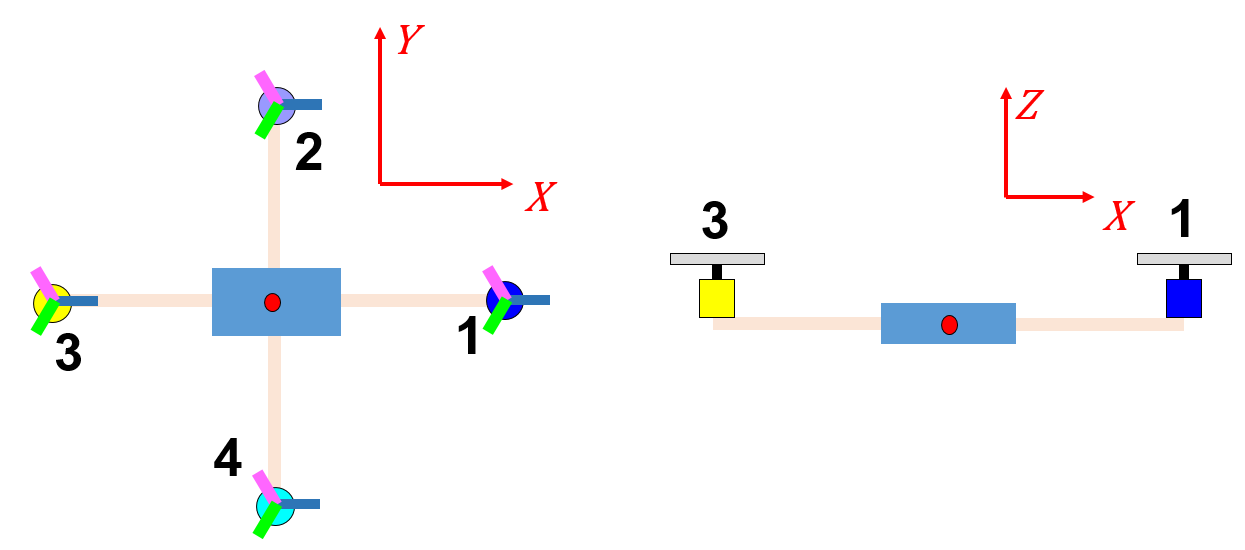

Let's decompose our quadcopter into 5 rigid bodies:

- $1\;x\;\textrm{body}\longrightarrow$ : the airframe

- $4\;x\;\textrm{body}\longrightarrow$ : each of the rotating propeller+rotor assemblies

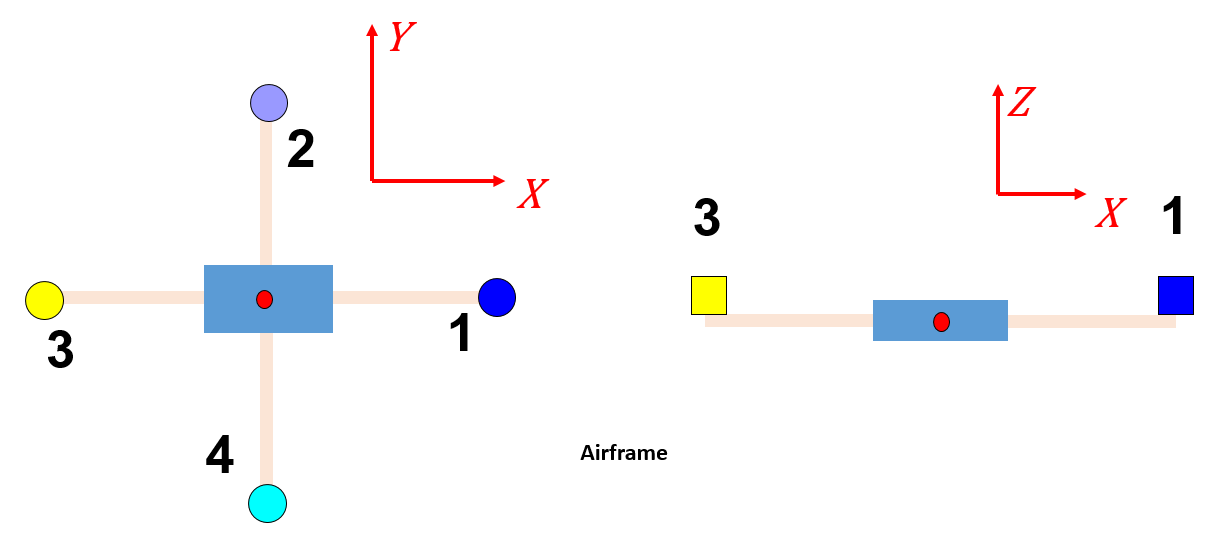            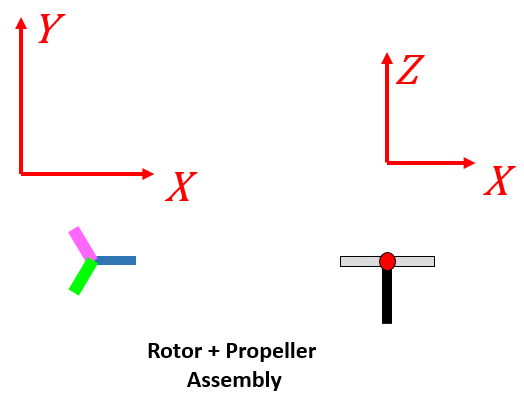

And Let's say that we know the Center of Mass of each of these bodies.  So what we need to do next is to compute the Kinetic and Potential energies of each of these components.  To do this, we'll need to know the following for each of our bodies:

- $^G_Gv$ *, CoM translational velocity vector is expressed in components of the {G}-frame*

- $^B_G\omega$*, angular velocity vector expressed in components of the {B}-frame*

- ${^GZ}$, CoM altitude *expressed in components of the {G}-frame*

**The AIRFRAME:**

v_com_airframe = [ diff(X(t),t);  diff(Y(t),t);  diff(Z(t),t) ];
w_airframe     = formula(  w  );
Z_airframe     = formula(  Z  );

**The PROPELLER assemblies :**

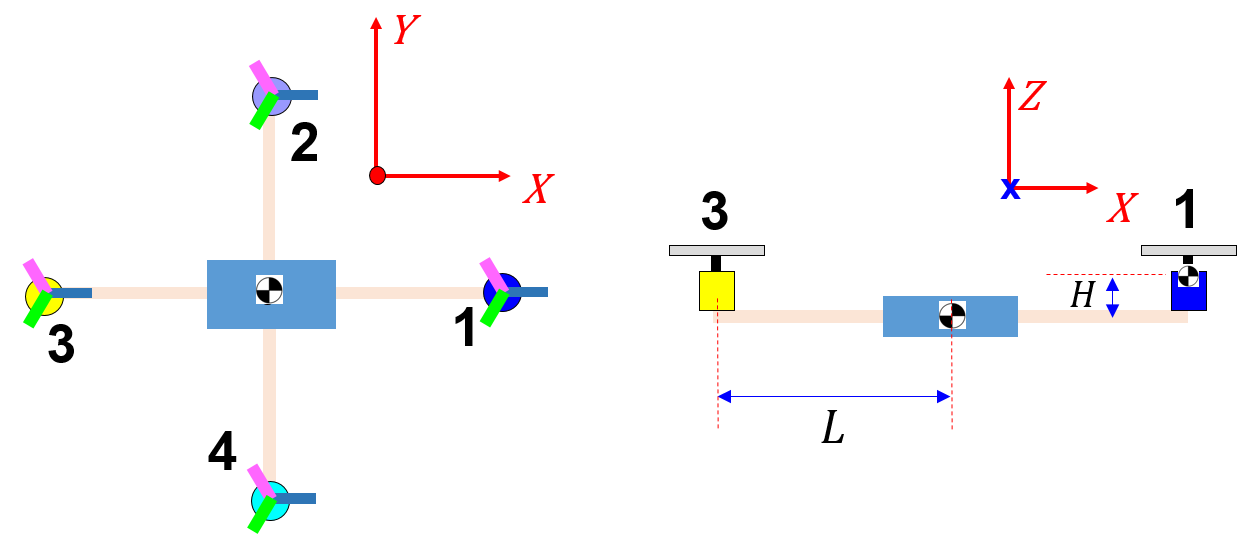  

syms     cg_to_mot_L                  cg_to_mot_H
L1_len = cg_to_mot_L;        H1_len = cg_to_mot_H;
L2_len = cg_to_mot_L;        H2_len = cg_to_mot_H;
L3_len = cg_to_mot_L;        H3_len = cg_to_mot_H;
L4_len = cg_to_mot_L;        H4_len = cg_to_mot_H;

So the vectors from the airframe's CoM to each CoM of the rotor+propeller assemblies are expressed by each column in the matrix below - the vectors are expressed in components of the airframe body fixed {B}-frame.

            % mot_#1    mot_#2      mot_#3     mot_#4
br_mat = [    L1_len,        0,    -L3_len,         0;
                   0,   L2_len,          0,   -L4_len;
              H1_len,   H2_len,     H3_len,    H4_len;   ];           

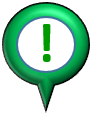 NOTE:  the rotational speeds of the propellers relative to the airframe are defined by the following MATLAB variables

- `wMOT_1  wMOT_2  wMOT_3  wMOT_4`

OK, let's compute the following:

- $^G_Gv$ *, CoM translational velocity vector is expressed in components of the {G}-frame*

- $^B_G\omega$*, angular velocity vector expressed in components of the {B}-frame*

- ${^GZ}$, CoM altitude *expressed in components of the {G}-frame*

for kk=1:4
    %-------------------------------------------------------    
    % compute local velocity due to rotation
    r              = br_mat(:,kk);
    vb_local       = formula( cross( w_airframe, r)  ); % == w x r
    % combine with airframe's CoM velocity
    v_air          = formula( v_com_airframe ); 
    vg             = v_air + gRb_again*vb_local; 
    v_prop_com_mat(:,kk)     = formula( vg );
    %-------------------------------------------------------
    tmp_rg           = formula( gRb_again * r );
    Z_prop_list(kk)  = formula(Z) +  tmp_rg(3);
    %-------------------------------------------------------
    w_prop_mat(:,kk) = formula(w_airframe) + [0;0;wMOT_list(kk)];    
end    

So what do these things look like ?

Here's the angular velocity of the airframe:

w_airframe

$$w\_airframe = \left(\begin{array}{c} \frac{\partial }{\partial t}\Psi \left(t\right)-\sin\left(\Theta \left(t\right)\right)\,\frac{\partial }{\partial t}\Phi \left(t\right)\\ \cos\left(\Psi \left(t\right)\right)\,\frac{\partial }{\partial t}\Theta \left(t\right)+\cos\left(\Theta \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)\,\frac{\partial }{\partial t}\Phi \left(t\right)\\ \cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right)\,\frac{\partial }{\partial t}\Phi \left(t\right)-\sin\left(\Psi \left(t\right)\right)\,\frac{\partial }{\partial t}\Theta \left(t\right) \end{array}\right)$$

Here's the TOTAL angular velocity of each propeller:

w_prop_mat          

# Airframe KE and PE:

Next we'll use our previously derived expressions for  velocities and use them to define the Kinetic Energy for airframe and propeller assemblies.  Because we've attached our BODY frames to the **centre of masses** of each body, the kinetic energy for the $i^{\textrm{th}}$ body can be stated as:

- 
$${\textrm{KE}}_i =\;\frac{1}{2}{v_{{\textrm{cm}}_i }^T {\ldotp m}_i } {\;\ldotp v}_{{\textrm{cm}}_i } \;\;\;+\;\;\;\;\;\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{\textrm{cm}}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual kinetic energies.   Similarly we can define our "system" Potential Energy as the sum of the "*N*" individual potential energies

- ${\textrm{KE}}_{\textrm{system}} =\;\sum_{i=1}^N {\textrm{KE}}_i$       and       ${P\mathrm{E}}_{\textrm{system}} =\;\sum_{i=1}^N {P\mathrm{E}}_i$

Start with the **airframe**:

KE = (1/2)*(v_com_airframe.')*m*(v_com_airframe)  + ...
     (1/2)*(    w_airframe.')*I*(    w_airframe) ;
 
PE = m*g*Z_airframe;

And then add the contributions from our 4 **propeller assemblies**:

for kk=1:4
    v_tmp = v_prop_com_mat(:,kk);
    w_tmp = w_prop_mat(:,kk);
    Z_tmp = Z_prop_list(kk);
    
    KE    = KE + (1/2)*(v_tmp.')*mprop*(v_tmp)  + ...
                 (1/2)*(w_tmp.')*Iprop*(w_tmp) ; 
             
    PE    = PE + mprop*g*Z_tmp;
end

# Now consider our Pendulum:

We have a pendulum sitting on top of the quadcopter.  Note the following about the pendulum:

- A spherical type joint allows the pendulum to rotate relative to the quadcopter's airframe. 

- The pendulum is represented by a rectangular solid, with dimensions $L_X \times L_Y \times L_Z$

- There is a "massless" rigid connection from the quadcopters CoM to the Spherical joint - this is represented by the offset distance $T_Z$

Note also some additional frames that we will attach to the pendulum and to the quadcopter airframe:

- {B}-frame is just the body fixed frame attached to the quadcopter's CoM

- {V}-frame is also a quadcopter body fixed frame and is offset from the {B}-frame

- {P}-frame is body fixed to the pendulum's CoM

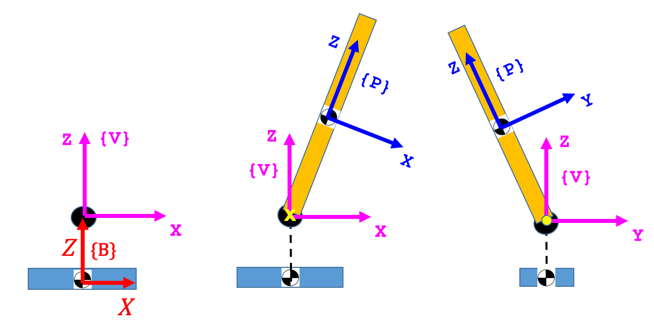

***Relative*** to the {V}-frame we will allow the pendulum to have it's own yaw, pitch and roll:

- R1Z occurs 1st about the LOCAL **Z** pendulum axis $(\phi_{pend})$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** pendulum axis $(\theta_{pend})$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** pendulum axis $(\psi_{pend})$, aka **ROLL**

## Euler angles for the pendulum:

syms        Phi_pend(t)      Theta_pend(t)       Psi_pend(t)    
syms    THE_Phi_pend     THE_Theta_pend      THE_Psi_pend

## Define our pendulum specific symbol lists:

actual_list_SYM_PEND_pos = [    Phi_pend(t),      Theta_pend(t),       Psi_pend(t) ];
holder_list_SYM_PEND_pos = [THE_Phi_pend,     THE_Theta_pend,      THE_Psi_pend    ];                             

## Defining some pendulum parameters:

syms  m_pend  
syms  Tv_Z_pend  Lx_pend  Ly_pend  Lz_pend

## Defining the pendulum INERTIA:

So let's define the INERTIA matrix for the pendulum about its body fixed **center of mass** {P}-frame:

   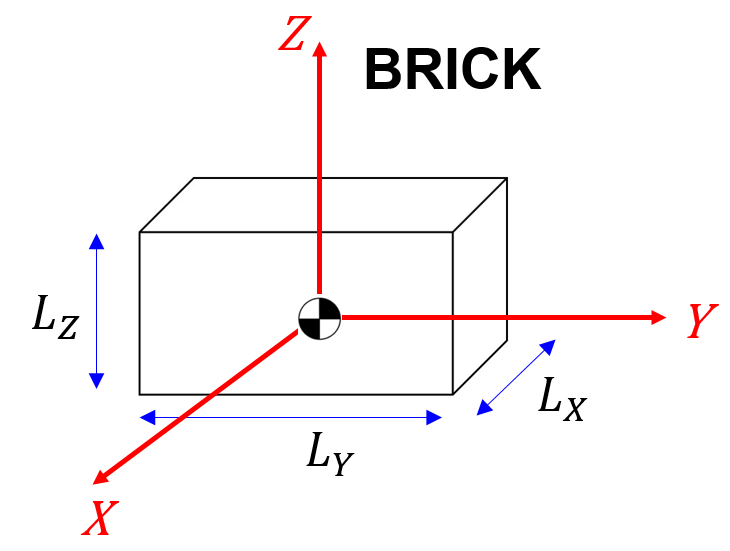

I_pend = ...
      m_pend *[    (Ly_pend^2 + Lz_pend^2)/12,    0,                    0; ...
                    0,                 (Lx_pend^2 + Lz_pend^2)/12,      0; ...
                    0,                  0,                   (Lx_pend^2 + Ly_pend^2)/12;] ; 

## Define some Direction Cosine Matrices:

The DCM relating the {P}-frame to the {V}-frame has the same "form" as the DCM relating the {B}-frame to the {G}-frame ... we just need to use the pendulum's relative Euler angles

                 % OLD_list          NEW_list
pRv = subs(bRg, [phi, theta, psi], [Phi_pend(t), Theta_pend(t), Psi_pend(t)]);
vRp = (pRv).';

## **Angular velocity of the pendulum:**

The angular velocity of the pendulum is the vector sum of the angular velocity of the airframe added to the relative angular velocity of the pendulum relative to the airframe.  When we do this vector sum we'll make sure that all vector components are in terms of the pendulum's {P}-frame

w_pend_part_1 = pRv * w_airframe;
w_pend_part_2 = LOC_calc_w_pend_relative_to_airframe();

w_pend        = w_pend_part_1   +  w_pend_part_2

## **Translational velocity of the pendulum CoM:**

First let's just compute the position of the pendulum's CoM and express in terms of the different frames:

- ***NOTE:*** $\left\lbrace \textrm{P2}\right\rbrace$ and $\left\lbrace P\right\rbrace$ are both BODY fixed frames attached to the pendulum, where $^Px$ is parallel to $^{P2}x$ and similarly for the Y and Z axes. 

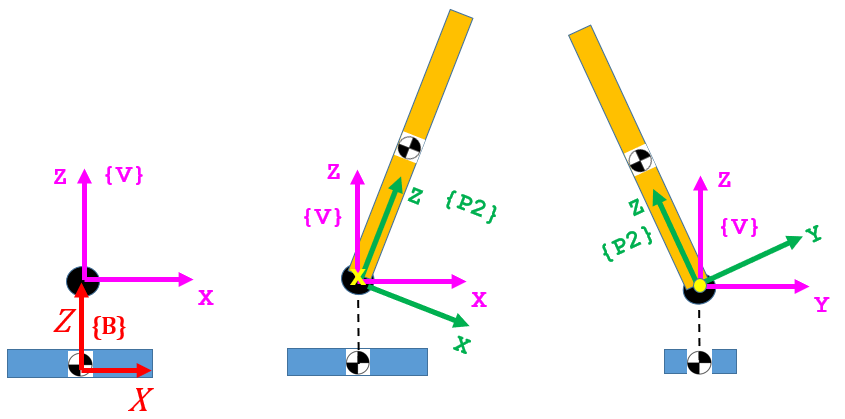

r_pend_p = [0;0;Lz_pend/2];      % pend COM according to a {P2}-frame that is at the spherical joint
r_pend_v = vRp * r_pend_p;       % pend COM in {V}-frame
r_pend_b = [0;0;Tv_Z_pend] + ...
           r_pend_v;             % pend COM in {B}-frame
r_pend_g = gRb_again * r_pend_b;
r_pend_g = r_pend_g  + [X(t); Y(t); Z(t)];

So the translational velocity of the pendulum's CoM expressed in components of the {G}-frame, is:

v_pend_g = diff(r_pend_g, t);
v_pend_g = formula( v_pend_g );  % make it an array of SYM

## **The pendulum's Kinetic and Potential energies:**

KE_pend    =     (1/2)*(v_pend_g.')*m_pend*(v_pend_g)  + ...
                 (1/2)*(w_pend.')  *I_pend*(w_pend) ; 
             
PE_pend    = m_pend * g * r_pend_g(3);

# The Total system Kinetic and Potential energies:

So combine the airframe(+propeller assemblies) and pendulum Kinetic and Potential energies:

KE = KE + KE_pend;
PE = PE + PE_pend;

# Prepare for the Computation of the Generalised Forces:

# 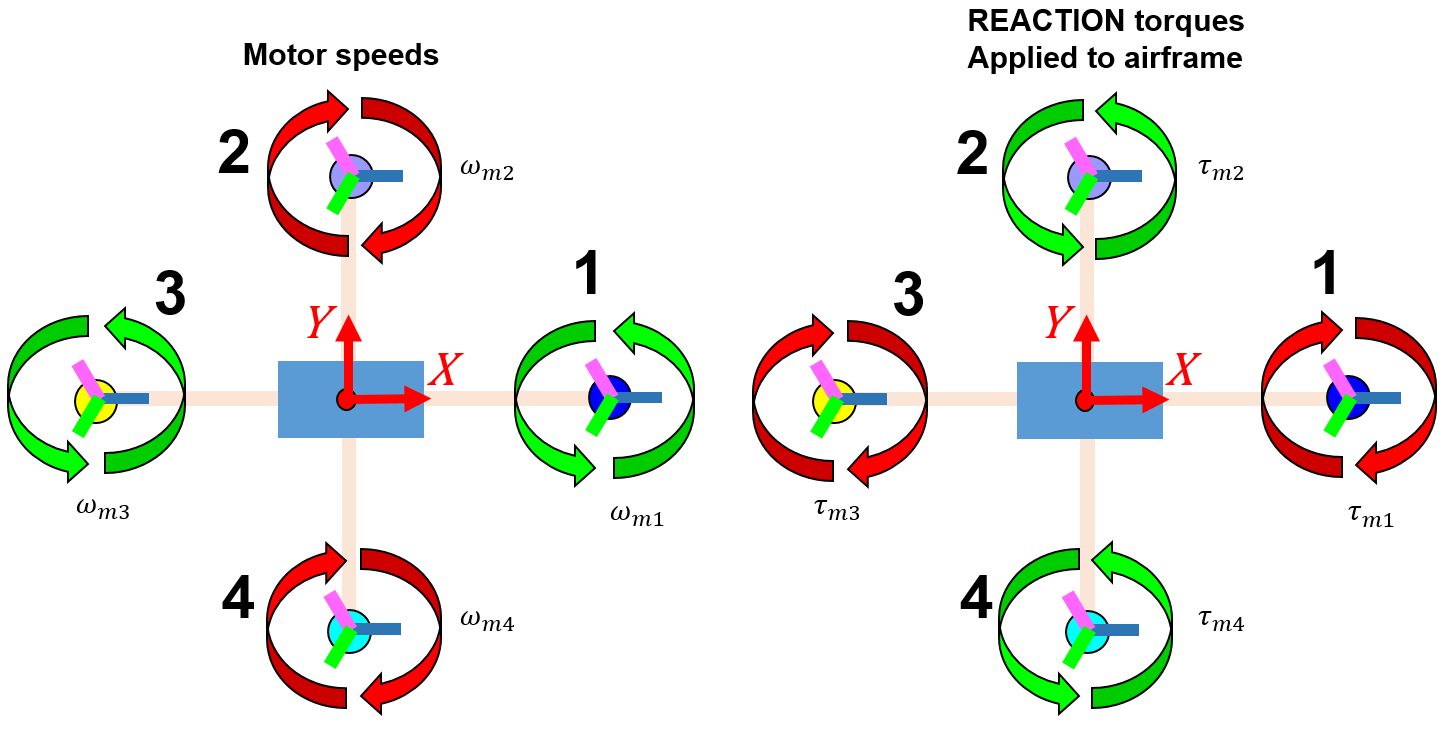 

Shortly we'll calculate the generalised force *Q* :


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


First we'll define the **yawing Torques** acting on the airframe and the angular velocity of the airframe: 

 NOTE:  the consistency of the frames for expressing $M$and $\omega$

- The moment vectors are expressed in **components of the BODY frame**

- The angular velocity vectors are expressed in **components of the BODY frame**

F_mat1 = [            0,          0,           0,           0;
                      0,          0,           0,           0;
                  Mbz_1,      Mbz_2,       Mbz_3,       Mbz_4;  ];
        
v_mat1 = [  w_airframe,  w_airframe,  w_airframe,  w_airframe]; 

v_mat1 = formula( v_mat1 ); % make things SYM not SYMFUN

And we also have the THRUST forces acting on the airframe which we need to convert into the {G}-frame.  The velocities at the point of application of these Forces are also expressed in {G}-frame components:

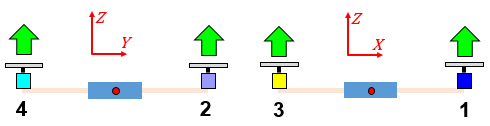

F_mat2 = gRb_again * ...
                    [     0,       0,       0,       0;
                          0,       0,       0,       0;
                      Tbz_1,   Tbz_2,   Tbz_3,   Tbz_4;  ];
        
v_mat2 = [    v_prop_com_mat ];  

 NOTE: the consistency of the frames for expressing $F$and $v$

- The Force vectors are expressed in **components of the INERTIAL frame**

- The velocity vectors are expressed in **components of the INERTIAL frame**

v_mat2 = formula( v_mat2 ); % make things SYM not SYMFUN
F_mat2 = formula( F_mat2 ); % make things SYM not SYMFUN

Combine these Torques and Forces into a single matrix and do the same for the translational and rotational velocities:

F_mat = [F_mat1, F_mat2];
v_mat = [v_mat1, v_mat2];

# Apply Lagrange's equation  

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $       where      $Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$

Where:

- *L = KE - PE, *is our system lagrangian

- $q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ}, \Phi_{pend}, \Theta_{pend}, \Psi_{pend} \}$ are the generalised co-ordinates 

- $Q_k$ are the generalised forces (Forces and Torques) for our system

Define our Complete list of generalised co-ordinates:

actual_list_SYM_pos  = [actual_list_SYM_pos,   actual_list_SYM_PEND_pos];
holder_list_SYM_pos  = [holder_list_SYM_pos,   holder_list_SYM_PEND_pos];

**Create a Generalised force object** using the class <`bh_genF4manips_CLS`>, and then we'll use it to compute the generalised forces:

genF_OBJ = bh_genF4manips_CLS( F_mat, ...
                               v_mat, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                 

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

**Create a Lagrangian object** using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

## **Compute the equations of motion:** 

We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then calculate the equations of motion:  

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

So what do the equations of motion actually look like ? - they are long equations involving many terms

% lag_OBJ.show_eom()

If you want to look at an individual equation of motion (eg: the LHS of the $4\textrm{th}$ equation), then you could do this:

lag_OBJ.get_eom(4, 'actual', 'LHS')

and similarly for the RHS:

lag_OBJ.get_eom(4, 'actual', 'RHS')

$$ans = {\mathrm{Tbz}}_{1}\,\left(\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)+{\mathrm{Tbz}}_{2}\,\left(\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)+{\mathrm{Tbz}}_{3}\,\left(\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)+{\mathrm{Tbz}}_{4}\,\left(\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)$$

# Convert symbolic EoM expressions into a block diagram model

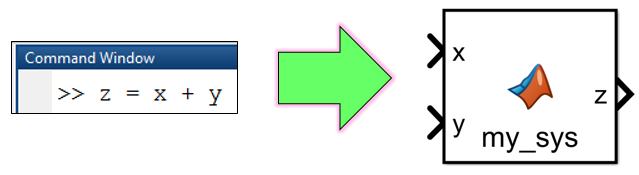

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks_A_b();

$$ans = \left(\begin{array}{c} {\mathrm{THE}}_{\Phi ,\mathrm{DD}}\\ {\mathrm{THE}}_{\Theta ,\mathrm{DD}}\\ {\mathrm{THE}}_{\Psi ,\mathrm{DD}}\\ {\mathrm{THE}}_{X,\mathrm{DD}}\\ {\mathrm{THE}}_{Y,\mathrm{DD}}\\ {\mathrm{THE}}_{Z,\mathrm{DD}}\\ {\mathrm{THE}}_{\Phi ,\mathrm{pend},\mathrm{DD}}\\ {\mathrm{THE}}_{\Theta ,\mathrm{pend},\mathrm{DD}}\\ {\mathrm{THE}}_{\Psi ,\mathrm{pend},\mathrm{DD}} \end{array}\right)$$

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'LoadFcn' for simulink/Sources/Waveform Generator
Callback: set_param(gcb,'LoadFlag','1');


Evaluating MaskInitialization for 'simulink/Sources/Waveform Generator': 'if (isequal(LoadFlag,'1'))     derivedSignals.DSMaskLoad(gcbh); end  if (isequal(ApplyFlag,'1'))    ...'.
Evaluating callback 'LoadFcn' for simulink/Sources/Signal Builder
Callback: sigbuilder_block('load');
Evaluating MaskInitialization for 'simulink/Sources/Signal Builder': 'if ~strcmp(get_param(bdroot(gcbh),'SimulationStatus'),'stopped') tuvar = sigbuilder_block('maskInit'...'.
Evaluating callback 'LoadFcn' for simulink/Sinks/XY Graph
Callback: sfunxy([],[],[],'LoadBlock')
Evaluating callback 'LoadFcn' for simulink/Model-Wide Utilities/Model Info
Callback: slcm LoadBlock;
Evaluating callback 'LoadFcn' for simulink/Math Operations/Slider Gain
Callback: sliderGain_cb(gcbh, 'load');


# And we're done !

fprintf('\n finised at %s', datestr(now,31))


 finised at 2021-01-11 14:05:00

# **Local functions:**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

The function below runs the above script and returns some of the symbols defined in the script.  When we call the script from inside the function, the variables created by the script are created in the "local" function workspace.

function [bRg, A] = LOC_collect_euler_concepts()
    
    % run the script inside our function
    bh_review_Euler_rates_and_wb
    
end

The cross product

function c = cross(a,b)

    c1 = a(2).*b(3)-a(3).*b(2);
    c2 = a(3).*b(1)-a(1).*b(3);
    c3 = a(1).*b(2)-a(2).*b(1);

    c  = [c1;c2;c3]; 

end

And the following function calculates the angular velocity of the pendulum relative to the airframe:

function w_pend_rel2air = LOC_calc_w_pend_relative_to_airframe(  )

syms        Phi_pend(t)      Theta_pend(t)       Psi_pend(t)    
syms    THE_Phi_pend     THE_Theta_pend      THE_Psi_pend

syms    phi_dot_pend 
syms  theta_dot_pend 
syms    psi_dot_pend


OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, ...
                    [THE_Phi_pend, THE_Theta_pend, THE_Psi_pend], 'SYM');

R1Z = OBJ_P.get_R1;
R2Y = OBJ_P.get_R2;
R3X = OBJ_P.get_R3;

aRv = R1Z;
cRa = R2Y;
pRc = R3X;
wp_part_1 = pRc * cRa * aRv * [0;0;phi_dot_pend];  
wp_part_2 = pRc * cRa *       [0;theta_dot_pend;0]; 
wp_part_3 = pRc *             [psi_dot_pend;0;0];   
 
wp = wp_part_1 + wp_part_2 + wp_part_3;

% now the symbols that I want my final result to have are:
%   Phi_pend(t)      Theta_pend(t)       Psi_pend(t)
% and their derivatives wrt time

OLD_LIST_pos = [THE_Phi_pend,    THE_Theta_pend,    THE_Psi_pend    ];
NEW_LIST_pos = [    Phi_pend(t),     Theta_pend(t),     Psi_pend(t) ];

OLD_LIST_vel = [     phi_dot_pend,           theta_dot_pend,        psi_dot_pend  ];
NEW_LIST_vel = [diff(Phi_pend(t),t),    diff(Theta_pend(t),t), diff(Psi_pend(t),t)];

OLD_LIST     = [ OLD_LIST_pos, OLD_LIST_vel ];
NEW_LIST     = [ NEW_LIST_pos, NEW_LIST_vel ];

w_pend_rel2air = wp;

w_pend_rel2air = subs(w_pend_rel2air, OLD_LIST, NEW_LIST);


end % function